N = 60;
lambdam = 2;
mu = 1/lambdam;
lambda = 0.5;
sigma = 1;
Omega = 0.6;

D = eye(N);

n_trials = 10000;
arrDet = zeros(1000,1);
for i=1:n_trials
    X1 = exprnd(lambdam, N);
    Y1 = cos(Omega*X1).*exp(-lambda*X1) / N;
    d1 = det(D + sigma*Y1);
    arrDet(i) = d1;
end

value1 = 1 + sigma*mu*(lambda + mu)/(Omega^2 + (lambda+mu)^2);
disp(value1);

    1.3676



disp(mean(arrDet));

    1.3662




[h,p,k,c] = lillietest(log(arrDet));

disp(p);

    0.5000



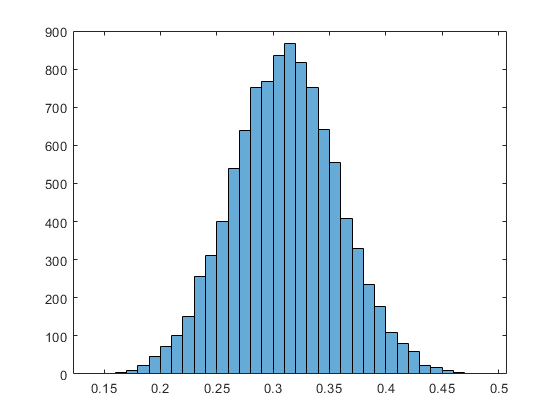


figure
histogram(log(arrDet));